clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[4.676;13.597;8.073];
u31=[0.301;0.855;0.421];
r2=[3.265;8.463;21.014];
u32=[-0.301;-0.855;0.421];
r3=[12.611;19.454;17.970];
u33=[0.301;-0.855;-0.421];
r4=[11.195;2.580;4.948];
u34=[-0.301;0.855;-0.421];
r5=[11.195;24.61;4.948];
u35=[-0.301;0.855;-0.421];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];
x10=[];
y10=[];
x11=[];
y11=[];

hold on 
axis([0 15 0 15]);
for R1=3:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     3.0000   15.1500    1.0035


ans =     3.3000   14.7500    1.0025


ans =     3.6000   14.3000    1.0046


ans =     3.9000   13.8500    1.0044


ans =     4.2000   13.4000    1.0014


ans =     4.5000   12.9000    1.0003


ans =     4.8000   12.3500    1.0005


ans =     5.1000   11.7500    1.0014


ans =     5.4000   11.1000    1.0027


ans =     5.7000   10.4000    1.0038


ans =     6.0000    9.7000    1.0007


ans =     6.3000    8.9000    1.0016


ans =     6.6000    8.0500    1.0035


ans =     6.9000    7.2500    1.0008


ans =     7.2000    6.4500    1.0009


ans =     7.5000    5.7000    1.0041


ans =     7.8000    5.1000    1.0037


ans =     8.1000    4.6000    1.0033


ans =     8.4000    4.2000    1.0002


ans =     8.7000    3.8000    1.0051


ans =     9.0000    3.5000    1.0018


ans =     9.3000    3.2000    1.0032


ans =     9.6000    2.9000    1.0085


ans =     9.9000    2.6500    1.0078


ans =    10.2000    2.4000    1.0090


ans =    10.5000    2.2000    1.0020


ans =    10.8000    1.9500    1.0057


ans =    11.1000    1.7500    1.0001


ans =    11.4000    1.5000    1.0049


ans =    11.7000    1.2500    1.0099


ans =    12.0000    1.0500    1.0049


ans =    12.3000    0.8000    1.0099


ans =    12.6000    0.6000    1.0047


ans =    12.9000    0.3500    1.0093



for R3=3:0.3:13 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =    15.1500    3.0000    1.0031


ans =    14.5000    3.3000    1.0018


ans =    13.8000    3.6000    1.0012


ans =    13.0500    3.9000    1.0015


ans =    12.2500    4.2000    1.0033


ans =    11.4500    4.5000    1.0034


ans =    10.6500    4.8000    1.0041


ans =     9.9000    5.1000    1.0036


ans =     9.2000    5.4000    1.0048


ans =     8.6000    5.7000    1.0048


ans =     8.1000    6.0000    1.0040


ans =     7.7000    6.3000    1.0011


ans =     7.3500    6.6000    1.0008


ans =     7.0500    6.9000    1.0017


ans =     6.8000    7.2000    1.0023


ans =     6.6000    7.5000    1.0006


ans = 1×3
    6.4000    7.8000    1.0042


ans = 1×3
    6.2500    8.1000    1.0028


ans = 1×3
    6.1000    8.4000    1.0051


ans = 1×3
    6.0000    8.7000    1.0001


ans = 1×3
    5.8500    9.0000    1.0084


ans = 1×3
    5.7500    9.3000    1.0081


ans = 1×3
    5.6500    9.6000    1.0096


ans = 1×3
    5.6000    9.9000    1.0008


ans = 1×3
    5.5000   10.2000    1.0054


ans = 1×3
    5.4000   10.5000    1.0113


ans = 1×3
    5.3500   10.8000    1.0057


ans = 1×3
    5.3000   11.1000    1.0010


ans = 1×3
    5.2000   11.4000    1.0100


ans = 1×3
    5.1500   11.7000    1.0067


ans = 1×3
    5.1000   12.0000    1.0039


ans = 1×3
    5.0500   12.3000    1.0017


ans = 1×3
    5.0000   12.6000    1.0000


ans = 1×3
    4.9000   12.9000    1.0127



for R3=13:-0.3:6 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    4.1000   13.0000    1.0000


ans = 1×3
    4.1000   12.7000    1.0112


ans = 1×3
    4.1500   12.4000    1.0048


ans = 1×3
    4.1500   12.1000    1.0176


ans = 1×3
    4.2000   11.8000    1.0135


ans = 1×3
    4.2500   11.5000    1.0110


ans = 1×3
    4.3000   11.2000    1.0100


ans = 1×3
    4.3500   10.9000    1.0108


ans = 1×3
    4.4000   10.6000    1.0132


ans = 1×3
    4.5000   10.3000    1.0028


ans = 1×3
    4.5500   10.0000    1.0094


ans = 1×3
    4.6500    9.7000    1.0045


ans = 1×3
    4.7500    9.4000    1.0028


ans = 1×3
    4.8500    9.1000    1.0043


ans = 1×3
    4.9500    8.8000    1.0091


ans = 1×3
    5.1000    8.5000    1.0061


ans = 1×3
    5.2500    8.2000    1.0076


ans = 1×3
    5.4500    7.9000    1.0036


ans = 1×3
    5.6500    7.6000    1.0048


ans = 1×3
    5.9000    7.3000    1.0022


ans = 1×3
    6.1500    7.0000    1.0045


ans = 1×3
    6.4500    6.7000    1.0034


ans = 1×3
    6.7500    6.4000    1.0061


ans = 1×3
    7.1000    6.1000    1.0043


for R1=7:0.3:11 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    7.0000    6.2000    1.0023


ans = 1×3
    7.3000    5.9500    1.0007


ans = 1×3
    7.6000    5.6500    1.0082


ans = 1×3
    7.9000    5.4000    1.0076


ans = 1×3
    8.2000    5.1500    1.0064


ans = 1×3
    8.5000    4.9000    1.0041


ans = 1×3
    8.8000    4.6500    1.0003


ans = 1×3
    9.1000    4.3500    1.0022


ans = 1×3
    9.4000    4.0500    1.0013


ans = 1×3
    9.7000    3.7000    1.0040


ans = 1×3
   10.0000    3.3500    1.0023


ans = 1×3
   10.3000    2.9500    1.0016


ans = 1×3
   10.6000    2.4500    1.0048


ans = 1×3
   10.9000    1.9000    1.0032



for R3=3:0.3:13 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
   
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
   10.3000    2.9500    1.0009


ans = 1×3
   10.0500    3.2500    1.0060


ans = 1×3
    9.8500    3.5000    1.0063


ans = 1×3
    9.5500    3.8500    1.0060


ans = 1×3
    9.3000    4.1500    1.0013


ans = 1×3
    9.0000    4.4500    1.0013


ans = 1×3
    8.6500    4.7500    1.0058


ans = 1×3
    8.3000    5.0500    1.0079


ans = 1×3
    7.9500    5.3500    1.0082


ans = 1×3
    7.6000    5.6500    1.0077


ans = 1×3
    7.2500    5.9500    1.0072


ans = 1×3
    6.9000    6.2500    1.0080


ans = 1×3
    6.6000    6.5500    1.0038


ans = 1×3
    6.3000    6.8500    1.0029


ans = 1×3
    6.0000    7.1500    1.0064


ans = 1×3
    5.8000    7.4000    1.0049


ans = 1×3
    5.5500    7.7500    1.0032


ans = 1×3
    5.3500    8.0500    1.0045


ans = 1×3
    5.2000    8.3500    1.0007


ans = 1×3
    5.0500    8.6500    1.0011


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


ans = 1×3
    5.0000    8.7500    1.0022


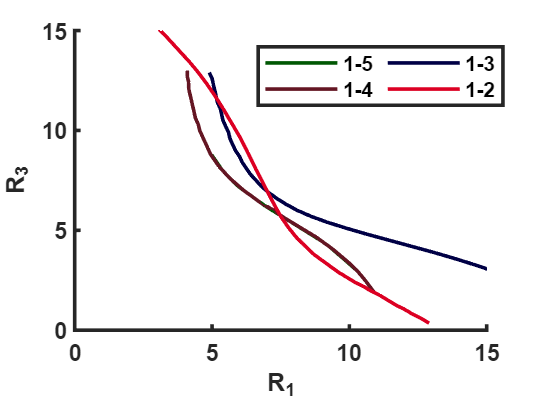


plot(x4,y4,'color',[0, 87, 3]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-5');

plot(x3,y3,'color',[100, 22, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-4');

plot(x2,y2,'color',[0, 0, 69]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-3');

plot(x1,y1,'color',[221, 0, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','1-2');







set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

